# **Formative task 4: Solution**

**Q1. Create an appropriate data store from the \cifar10Train" folder containing the four categories bird, horse, ship and truck. These will be your categories used to label the data during training. Each image should be categorized and labelled by the name of the folder it is saved in e.g. all images in folder \horse" should be categorized and labelled as horse. The resulting data store will be your training data set.**


categories = {'bird','horse','ship','truck'};
rootFolder = 'cifar10Train';
Trainds = imageDatastore(fullfile(rootFolder, categories), ... 
    'LabelSource', 'foldernames');

**Q2. Create an appropriate data store from the \cifar10Test" folder containing the four datasets bird, horse, ship and truck similarly to Question 1. The resulting data store will be your test dataset**

rootFolder = 'cifar10Test';
Testds = imageDatastore(fullfile(rootFolder, categories), ...
    'LabelSource', 'foldernames');

**Q3. Define the layers which will form your CNN. This network will consist of 15 layers. These layers should be:**

- **input layer**

- **2d convolution layer**

- **2d max pooling layer**

- **relu layer**

- **2d convolution layer**

- **relu layer**

- **2d average pooling layer**

- **2d conculution layer**

- **relu layer**

- **2d average pooling layer**

- **2d convolution layer**

- **relu layer**

- **fully connected layer**

- **soft max alyer**

- **classification layer**

**For the 2d convolution layers 32 filters of size 3 should be applied with padding of 4 and bias learn rate factor of 2 also use this factor for the fully connected layer. For the pooling layers use a pool size of 3 and a stride of 2**

dimensions = 32;
layers = [
    imageInputLayer([dimensions dimensions 3]);
    convolution2dLayer(3,dimensions,'Padding',4,'BiasLearnRateFactor',2);
    maxPooling2dLayer(3,'Stride',2);
    reluLayer();
    convolution2dLayer(3,dimensions,'Padding',4,'BiasLearnRateFactor',2);
    reluLayer();
    averagePooling2dLayer(3,'Stride',2);
    convolution2dLayer(3,dimensions,'Padding',4,'BiasLearnRateFactor',2); 
    reluLayer();
    averagePooling2dLayer(3,'Stride',2);
    convolution2dLayer(3,dimensions,'Padding',4,'BiasLearnRateFactor',2);
    reluLayer();
    fullyConnectedLayer(4,'BiasLearnRateFactor',2);
    softmaxLayer()
    classificationLayer()];


**Q4. Define training options for the CNN, the is a large variety of changes you can make to the way the network is trained, to start set the following parameters. **

- **Use a stochastic gradient descent with momentum optimizer**

- **Set the the maxium number of Epochs to 10**

- **Set the mini batch size to 100**

- **Set the initial learn rate to 0.001**

- **Set the learn rate scedule to piecewise**

- **Set the L2 Regularization to 0.004**

- **Set the learn rate drop period to 8**

- **Set the learn rate drop factor to 0.1**

- **Create a training progress output plot**

specs = trainingOptions('sgdm', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 100, ...
    'InitialLearnRate', 0.001, ...
    'Plots','training-progress',...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 8, ...
    'LearnRateDropFactor', 0.1, ...
    'L2Regularization', 0.004);


**Q5. Now that you created the train and test dataset (Q1 and Q2), need the CNN architecture (Q3) and set the training options (Q4) use the trainNetwork MATLAB function3 to train your model using the train dataset. Then run the trained network on the test dataset, which was not used to train the network, to check the accuracy of your model.**

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:02 |       22.00% |       3.2077 |          0.0010 |


|       1 |          50 |       00:00:17 |       57.00% |       1.0126 |          0.0010 |


|       1 |         100 |       00:00:31 |       61.00% |       0.9500 |          0.0010 |


|       1 |         150 |       00:00:46 |       76.00% |       0.7649 |          0.0010 |


|       1 |         200 |       00:01:00 |       77.00% |       0.6448 |          0.0010 |


|       2 |         250 |       00:01:14 |       72.00% |       0.7337 |          0.0010 |


|       2 |         300 |       00:01:28 |       78.00% |       0.5286 |          0.0010 |


|       2 |         350 |       00:01:43 |       76.00% |       0.6752 |          0.0010 |


|       2 |         400 |       00:01:57 |       81.00% |       0.4999 |          0.0010 |


|       3 |         450 |       00:02:12 |       76.00% |       0.6939 |          0.0010 |


|       3 |         500 |       00:02:26 |       84.00% |       0.4830 |          0.0010 |


|       3 |         550 |       00:02:41 |       76.00% |       0.6361 |          0.0010 |


|       3 |         600 |       00:02:55 |       79.00% |       0.5002 |          0.0010 |


|       4 |         650 |       00:03:11 |       78.00% |       0.6566 |          0.0010 |


|       4 |         700 |       00:03:26 |       86.00% |       0.4551 |          0.0010 |


|       4 |         750 |       00:03:40 |       79.00% |       0.5573 |          0.0010 |


|       4 |         800 |       00:03:55 |       79.00% |       0.4694 |          0.0010 |


|       5 |         850 |       00:04:09 |       80.00% |       0.6042 |          0.0010 |


|       5 |         900 |       00:04:23 |       89.00% |       0.3694 |          0.0010 |


|       5 |         950 |       00:04:35 |       82.00% |       0.5256 |          0.0010 |


|       5 |        1000 |       00:04:46 |       80.00% |       0.4303 |          0.0010 |


|       6 |        1050 |       00:05:00 |       81.00% |       0.5707 |          0.0010 |


|       6 |        1100 |       00:05:11 |       89.00% |       0.3316 |          0.0010 |


|       6 |        1150 |       00:05:23 |       80.00% |       0.5001 |          0.0010 |


|       6 |        1200 |       00:05:34 |       81.00% |       0.4107 |          0.0010 |


|       7 |        1250 |       00:05:46 |       81.00% |       0.5431 |          0.0010 |


|       7 |        1300 |       00:05:57 |       89.00% |       0.3177 |          0.0010 |


|       7 |        1350 |       00:06:09 |       82.00% |       0.4860 |          0.0010 |


|       7 |        1400 |       00:06:20 |       83.00% |       0.3979 |          0.0010 |


|       8 |        1450 |       00:06:32 |       81.00% |       0.5178 |          0.0010 |


|       8 |        1500 |       00:06:43 |       89.00% |       0.2972 |          0.0010 |


|       8 |        1550 |       00:06:55 |       84.00% |       0.4682 |          0.0010 |


|       8 |        1600 |       00:07:06 |       88.00% |       0.3883 |          0.0010 |


|       9 |        1650 |       00:07:19 |       82.00% |       0.4952 |          0.0001 |


|       9 |        1700 |       00:07:31 |       93.00% |       0.2545 |          0.0001 |


|       9 |        1750 |       00:07:42 |       84.00% |       0.4643 |          0.0001 |


|       9 |        1800 |       00:07:54 |       87.00% |       0.3278 |          0.0001 |


|      10 |        1850 |       00:08:10 |       84.00% |       0.4735 |          0.0001 |


|      10 |        1900 |       00:08:23 |       93.00% |       0.2347 |          0.0001 |


|      10 |        1950 |       00:08:36 |       84.00% |       0.4538 |          0.0001 |


|      10 |        2000 |       00:08:49 |       87.00% |       0.3239 |          0.0001 |


|========================================================================================|


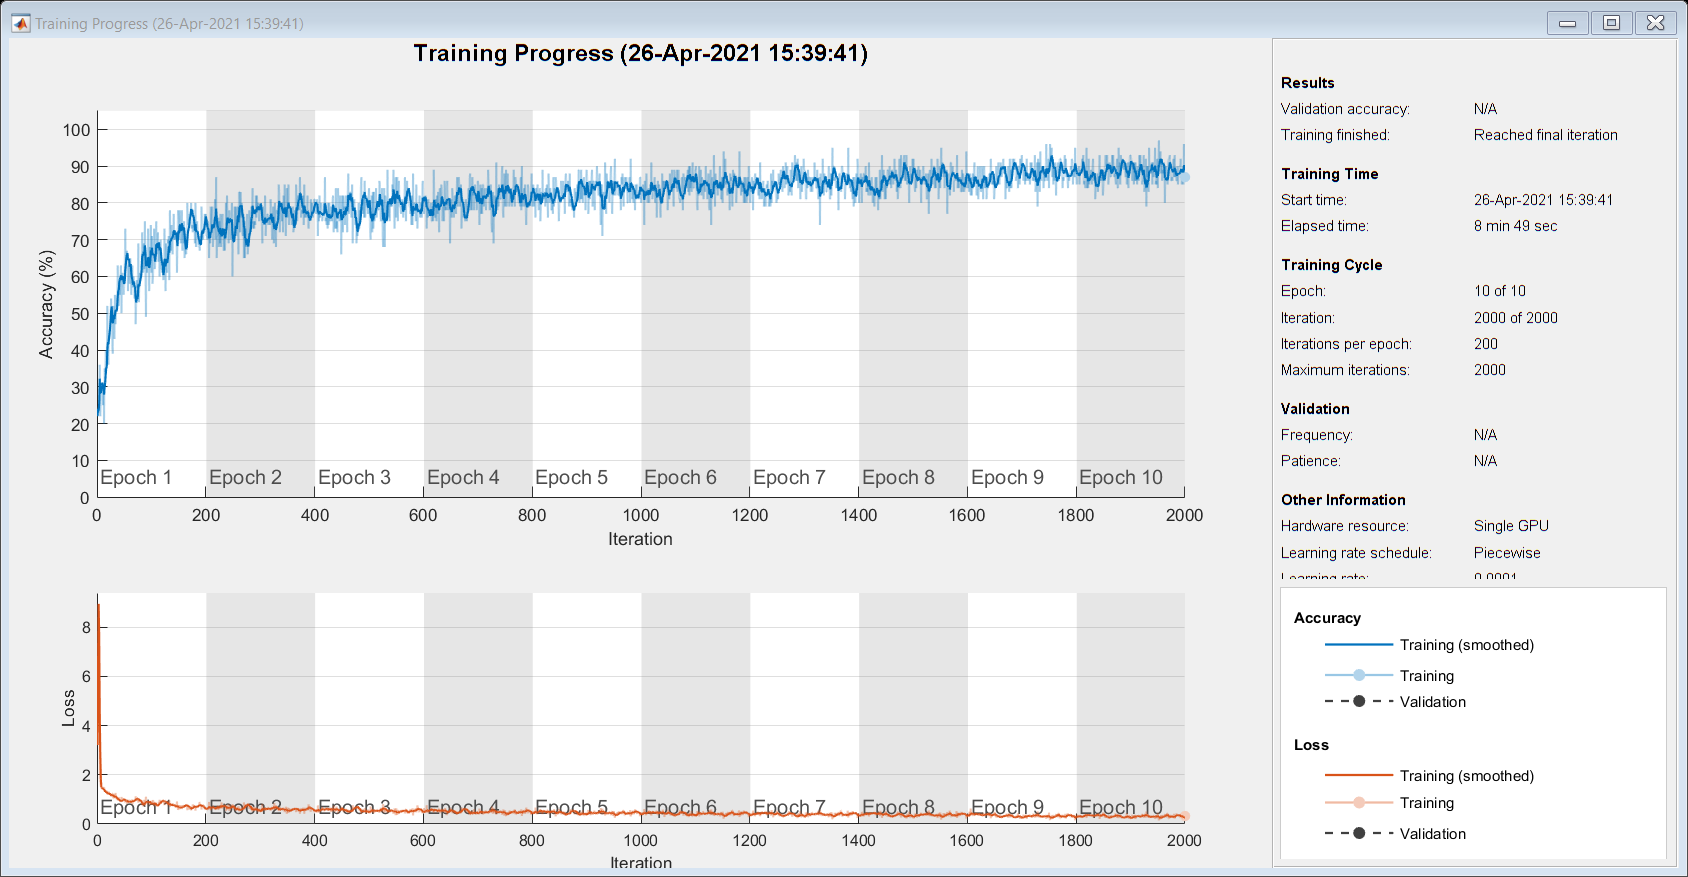

[net, info] = trainNetwork(Trainds, layers, specs);

climages = classify(net,Testds);
confMat = confusionmat(Testds.Labels, climages);
confMat = confMat./sum(confMat,2);
Acuaracy = (mean(diag(confMat)))*100

Acuaracy = 86.5000

**Q6.Once you have completed the previous tasks try changing the training options to see how they influence the accuracy of your model. Read more about the available training optionshere Based on your observations, how could the accuracy be improved using different training options?**